close all;

font=24;
line_width=2;

#### Saving pressure curves

save  out_noordergraaf_rideout_Aorta_Ascendens.mat out


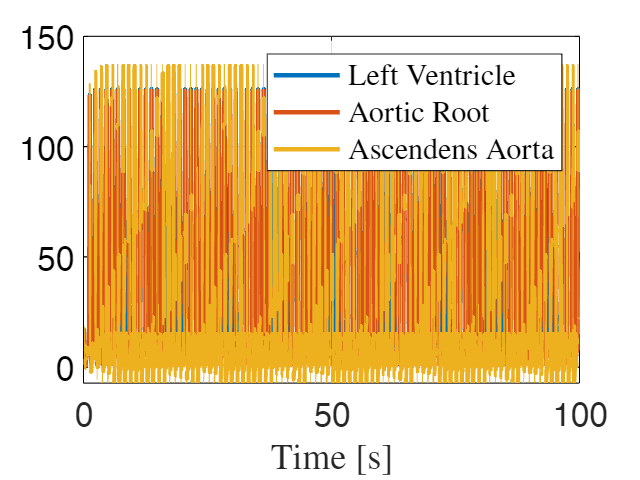

fontsize=15;
figure;
time=out.P_Aortic_Root.Time;

plot(time,reshape(out.P_LV.data,1,length(time)),'LineWidth',2); hold on;

plot(time,reshape(out.P_Aortic_Root.data,1,length(time)),'LineWidth',2);

plot(time,reshape(out.P_AAsc_in.data,1,length(time)),'LineWidth',2);

grid on;
xlabel('Time [s]','Interpreter','latex');
legend({'Left Ventricle','Aortic Root','Ascendens Aorta'},'Interpreter','latex');
set(gca,'FontSize',fontsize);
% title(title_plot{selector},'Interpreter','latex');
set(gca,"YColor",'black');